% Pomiary charakterystyki statycznej
clear
steer_vect = [-0.8 -0.7 -0.6 -0.5 -0.4 -0.3 -0.2 -0.1 0 0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8];    % [-] 
rpm_vect = [-2929 -2705 -2455 -2245 -1952 -1593 -1176 -667 0 673 1213 1614 1987 2269 2569 2823 2983 ];  % [RPM] 
motor_vect = [-17.93 -15.69 -13.44 -11.20 -8.98 -6.71 -4.47 -2.213 0 2.215 4.48 6.72 8.97 11.2 13.43 15.67 17.92 ];     % [V]
tacho_vect = [-1.486 -1.392 -1.268 -1.153 -0.998 -0.811 -0.601 -0.342 0 0.35 0.621 0.826 1.002 1.173 1.322 1.446 1.555 ];  % [V]

% Wyrysowanie charakterystyki tachoprądnicy
figure
P = polyfit(rpm_vect, tacho_vect, 1)

P =     0.0005    0.0020


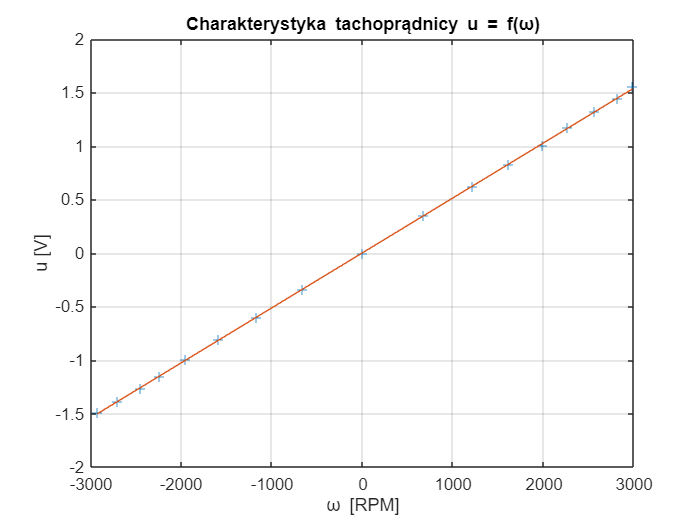

plot(rpm_vect, tacho_vect, '+'); grid on; hold on
plot(rpm_vect, polyval(P, rpm_vect)); hold off
title("Charakterystyka tachoprądnicy u = f(\omega)")
xlabel("\omega [RPM]")
ylabel("u [V]")
xlim([-3000 3000])
ylim([-2 2])

% Wyrysowanie charakterystyki silnika
figure
p = polyfit(rpm_vect, motor_vect, 3)

p =     0.0000   -0.0000    0.0034    0.0410


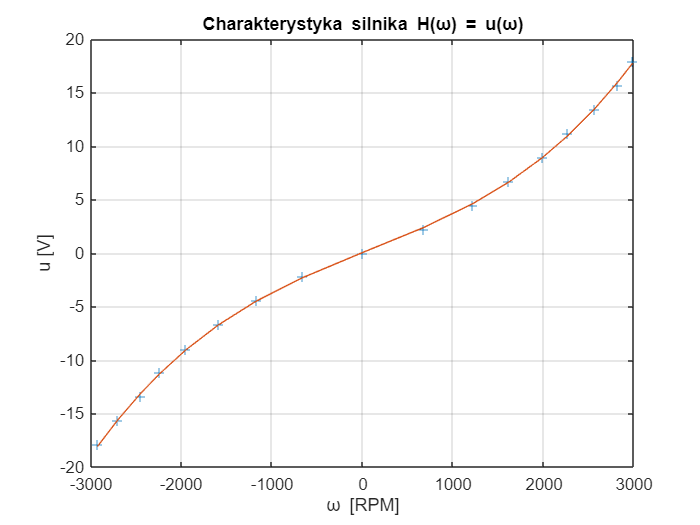

plot(rpm_vect, motor_vect, '+'); grid on; hold on
plot(rpm_vect, polyval(p, rpm_vect)); hold off
title("Charakterystyka silnika H(\omega) = u(\omega)")
xlabel("\omega [RPM]")
ylabel("u [V]")
xlim([-3000 3000])
ylim([-20 20])

% Charakterystyka silnika 
figure
H = polyfit(rpm_vect, steer_vect, 3)

H =     0.0000   -0.0000    0.0002    0.0017


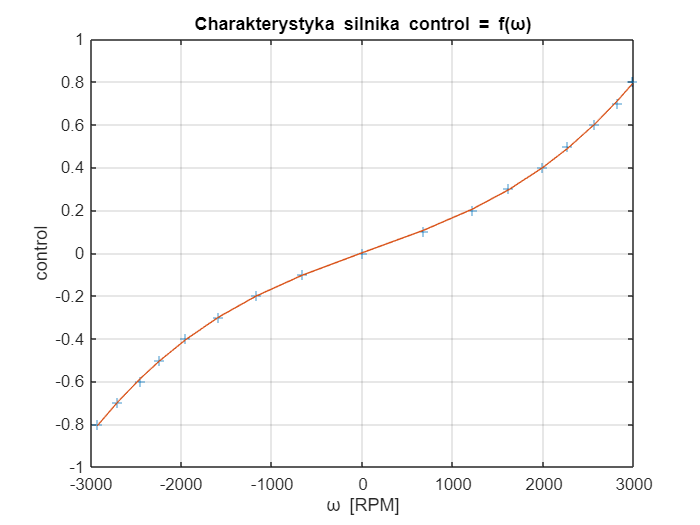

H_reversed = polyfit(steer_vect, rpm_vect, 3);
plot(rpm_vect, steer_vect, '+'); grid on; hold on
plot(rpm_vect, polyval(H, rpm_vect)); hold off
title("Charakterystyka silnika control = f(\omega)")
xlabel("\omega [RPM]")
ylabel("control")
xlim([-3000 3000])
ylim([-1 1])

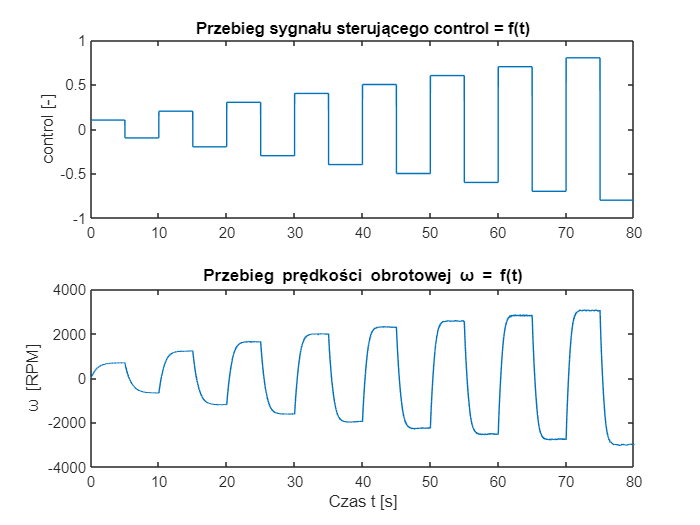

% Generowanie sygnalu prostokatnego z rosnaca amplituda, za pomoca bloczka signal builder 
t = [0 1 1 2 2 3 3 4 4 5 5 6 6 7 7 8 8 9 9 10 10 11 11 12 12 13 13 14 14 15 15 16] .*5;
y = [1  1 -1 -1 2 2 -2 -2 3 3 -3 -3 4 4 -4 -4 5 5 -5 -5 6 6 -6 -6 7 7 -7 -7 8 8 -8 -8] .*0.1;

%input = silnik.signals(1).values;
%pitch = silnik.signals(2).values;
%rpm = silnik.signals(3).values;
%time = silnik.time;
%save("przebiegi_dynamiczne_silnika.mat", "input", "pitch", "rpm", "time")

load("przebiegi_dynamiczne_silnika_prost_naras.mat")
figure

subplot(2, 1, 1);
plot(time, input);
title("Przebieg sygnału sterującego control = f(t)");
ylabel("control [-]")
subplot(2, 1 , 2);
plot(time, rpm);
title("Przebieg prędkości obrotowej \omega = f(t)");
xlabel("Czas t [s]")
ylabel("\omega [RPM]")

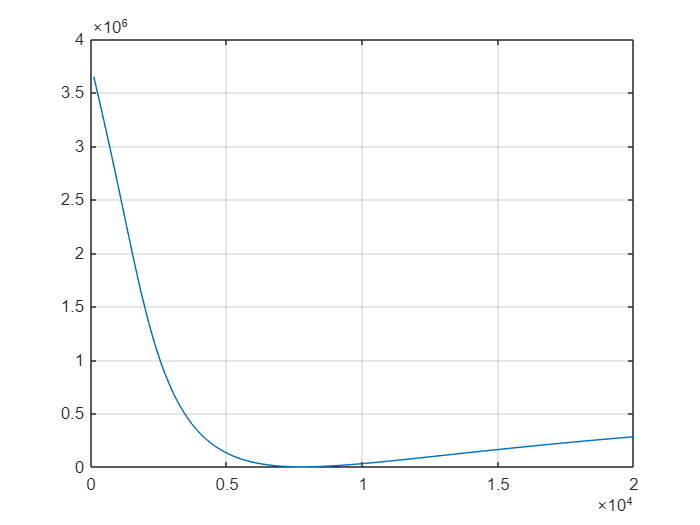

% Wyznaczenie optymalnej wartosci K w rownaniu w' = K(u - H(w)), za pomocą
% metody najmniejszych kwadratów.
m_vec = [];
K = 100:100:20000;
for k = K % Dla różnych wartości k
    [~, x] = rk4_silnik(0, input, 80, k, H); % wyliczenie przebiegu za pomocą rk4 
    m = mean((rpm - x).^2); % wyliczenie błędu 
    m_vec = [m_vec, m]; % dodanie wyniku do wektora
end

figure
plot(K, m_vec); grid on;

% Optymalna wartosc K_opt 
[~, i] = min(m_vec);
K_opt = K(i)

K_opt = 7800

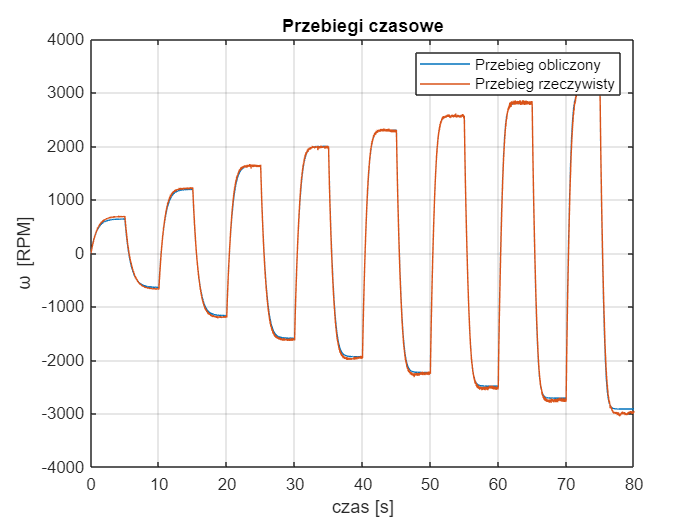

[time, x] = rk4_silnik(0, input, 80, K_opt, H);
% Porownanie przebiegu zmierzonego i wyliczonego dla sygnału prostokątnego
% o narastającej amplitudzie
figure
plot(time, x); grid on; hold on; 
plot(time, rpm); hold off;
title("Przebiegi czasowe")
legend("Przebieg obliczony", "Przebieg rzeczywisty")
xlabel("czas [s]")
ylabel("\omega [RPM]")

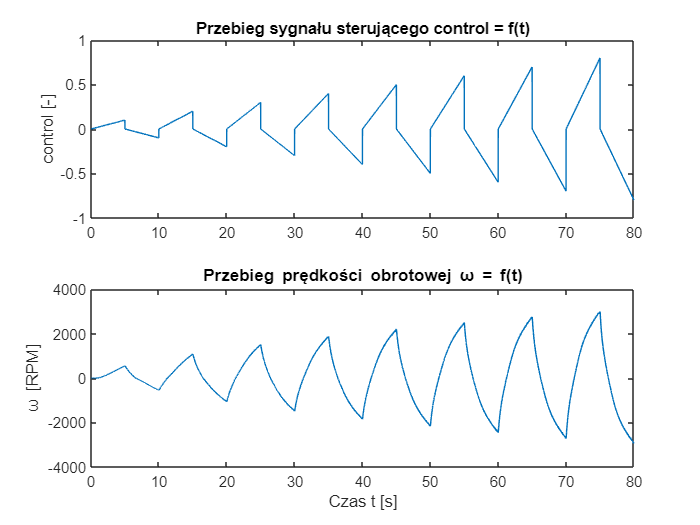

% Generowanie sygnału piłozębnego z amplitudą narastającą w czasie i
% rysowanie charakterystyki modelu 

t = [0 1 1 2 2 3 3 4 4 5 5 6 6 7 7 8 8 9 9 10 10 11 11 12 12 13 13 14 14 15 15 16] .*5;
y = [0 1 0 -1 0 2 0 -2 0 3 0 -3 0 4 0 -4 0 5 0 -5 0 6 0 -6 0 7 0 -7 0 8 0 -8] .*.1;

%input = silnik.signals(1).values;
%pitch = silnik.signals(2).values;
%rpm = silnik.signals(3).values;
%time = silnik.time;
%save("przebiegi_dynamiczne_silnika_piłoz_narast.mat", "input", "pitch", "rpm", "time");

load("przebiegi_dynamiczne_silnika_piłoz_narast.mat")
figure
subplot(2, 1, 1);
plot(time, input);
title("Przebieg sygnału sterującego control = f(t)");
ylabel("control [-]")
subplot(2, 1 , 2);
plot(time, rpm);
title("Przebieg prędkości obrotowej \omega = f(t)");
xlabel("Czas t [s]")
ylabel("\omega [RPM]")

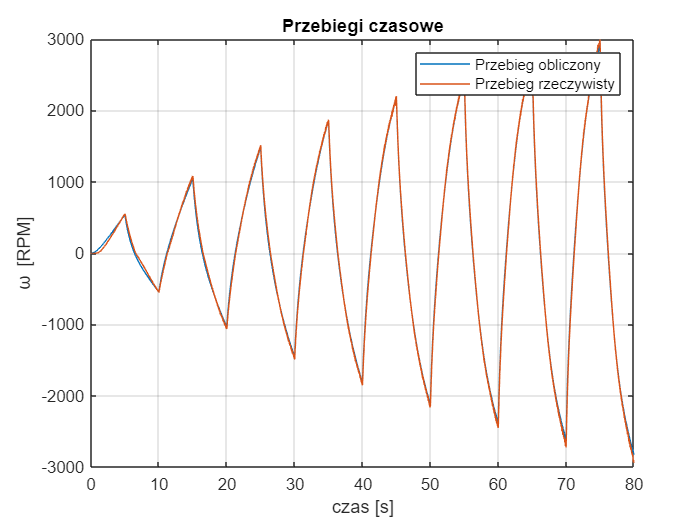

% Porównanie przebiegów piłokształtnych narastających
figure
[time, x] = rk4_silnik(0, input, 80, K_opt, H);
plot(time, x); grid on; hold on; 
plot(time, rpm); hold off;
title("Przebiegi czasowe")
legend("Przebieg obliczony", "Przebieg rzeczywisty")
xlabel("czas [s]")
ylabel("\omega [RPM]")

% Zapis wspolczynnikow do pliku
save("idenyfikacja_silnika_zmienne", "K_opt", "P", "H", "H_reversed")